# Access ORNL DAAC WMS Service using Matlab

*Author: ORNL DAAC*

*Date: April 2, 2018*

*Contact for <https://daac.ornl.gov/ ORNL DAAC>: uso@daac.ornl.gov*

**Keywords: SDAT, WMS, OGC Web Service, Matlab, Mapping Toolbox**

## Overview

In this tutorial, we will explore how to access ORNL DAAC OGC WMS Service using Matlab Plugin [Mapping Toolbox](https://www.mathworks.com/help/map/). Mapping Toolbox provides tools and utilities for analyzing geographic data and creating map displays. In this example, web-based data is imported from Web Map Service (WMS) servers. WMS provides a simple HTTP interface for requesting geo-registered map images from one or more distributed geospatial databases. The WMS request is also available from data downloading page of ORNL DAAC Spatial Data Access Tool (SDAT). After connecting to ORNL DAAC WMS service, we will find target layer by searching by keywords. For this example, Amazon river basin percipitation 1972-1992 is used for demonstration. Then we will learn how to get available metadata of this WMS service layer. At last, we will walkthrough how to send request to map the data and plot the legend.

## Source Data

The Amazon River Basin precipitation data in 1972 derived from the gauging network operated by the Divisao Nacional de Aguas e Energia Eletrica was used in this tutorial. The original GeoTIFF file is accessible from [ORNL DAAC's Spatial Data Access Tool.](https://webmap.ornl.gov/ogcdown/wcsdown.jsp?dg_id=228_1)

## Prerequisites

Matlab R2016a or later. Matlab plugin: Mapping toolbox

## Procesure

**1. Connect to ORNL DAAC WMS service**

% connect to ORNL DAAC WMS service 
server_url = 'http://webmap.ornl.gov/ogcbroker/wms'; 
server = WebMapServer(server_url); 
% retrieve WMS service capabilities
capabilities = wmsinfo(server_url); 
capabilities

capabilities =   WMSCapabilities

  Properties:
         ServerTitle: 'ORNL DAAC WMS Server'
           ServerURL: 'http://webmap.ornl.gov/ogcbroker/wms'
         ServiceName: 'OGC:WMS'
             Version: '1.1.1'
            Abstract: 'The ORNL DAAC provides access to various geospatial data, including ORNL DAAC archived data through Open Geospatial Consortium (OGC) standards-based Web Map Service (WMS) version 1.1.1.'
      OnlineResource: '<a href = "https://webmap.ornl.gov/ogcbroker/wms?">https://webmap.ornl.gov/ogcbroker/wms?</a>'
  ContactInformation: [1x1 struct]
   AccessConstraints: ''
                Fees: ''
         KeywordList: {'WMS' 'ORNL' 'DAAC'}
        ImageFormats: {9x1 cell}
          LayerNames: {16477x1 cell}
               Layer: [16477x1 WMSLayer]
          AccessDate: '03-Apr-2018'

  Methods


**2. Search layer by keywords and get available value of time dimension**

% search layers with keywords "amazon rain 1972" in title 
results=capabilities.Layer.refine('amazon*rain*1972', 'SearchFields', 'LayerTitle'); 
results

results =   WMSLayer

  Properties:
           Index: 1
     ServerTitle: 'ORNL DAAC WMS Server'
       ServerURL: 'http://webmap.ornl.gov/ogcbroker/wms'
      LayerTitle: 'Amazon Rain fall 1972 (All months)'
       LayerName: '228_1'
          Latlim: [-20.0000 5.2000]
          Lonlim: [-79.6000 -49.4000]
        Abstract: ''
CoordRefSysCodes: {'EPSG:4326'}
         Details: [1x1 struct]

  Methods


% retrieve the target layer from results  
rain = results(1); 
% show name and value of dimensions in target layer 
rain.Details.Dimension.Name 

ans = 'time'

rain.Details.Dimension.Extent 

ans = '1972-01/1972-12/P1M'

**3. Get map of Amazon rainfall in June, 1972:**

% construct a WMS request with default parameters
request=WMSMapRequest([rain], server);
% set time step
request.Time = '1972-06';
% set image format
request.ImageFormat = 'image/png';
% send request to ORNL DAAC WMS
A=server.getMap(request.RequestURL); 

**4. Display requested map in a figure**

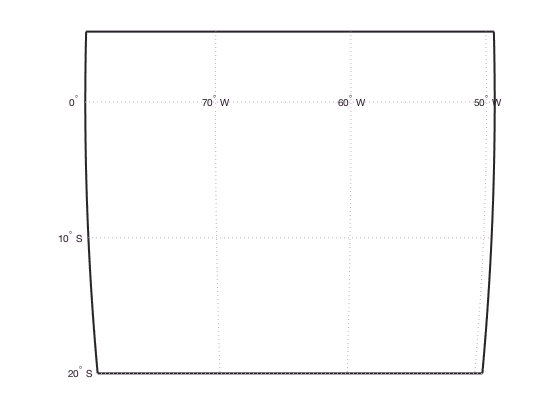

% get map dimension
R=request.RasterRef;
figure;
% render background map
ax=worldmap(A, R);

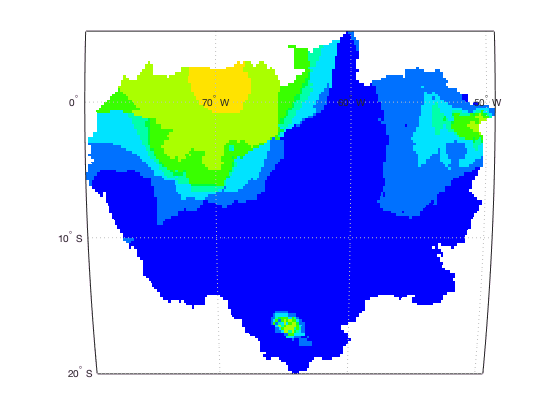

% render Amazon rain fall map in June, 1972
geoshow(A, R);

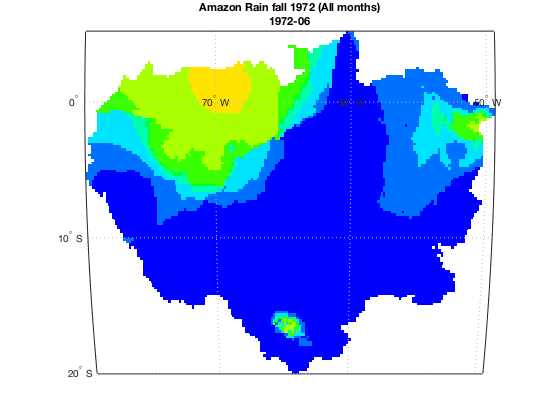

% add map title
title({rain.LayerTitle, request.Time}); 

**5. Request and display map legend**

% request map legend
legend_url = rain.Details.Style(1).LegendURL.OnlineResource;
legend_url

legend_url = 'https://webmap.ornl.gov/ogcbroker/wms?version=1.1.1&service=WMS&request=GetLegendGraphic&layer=228_1&format=image/png&STYLE=default'

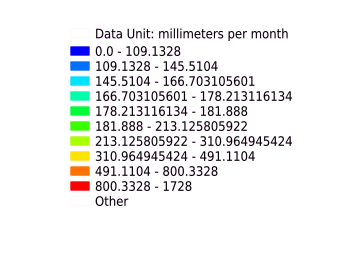

% alpha is required here to deal with transparent PNG image
[legend, cmap, alpha] = imread(legend_url);
% display map legend image
f = imshow(legend);
%set transparency of image background
set(f,'AlphaData',alpha);
axis off;